动机：长时间的积水会带来更持久的破坏。积水的时长与许多因素有关，目前知道的包括坡度、曼宁系数、透水率等等。此外，积水时长是否与发展水平、等等有关？

实验目的：探究渍水时长和渍水区域的贫富之间的相关性。

数据：

1.历史洪涝duration数据

[Global Flood Database (cloudtostreet.info)](http://global-flood-database.cloudtostreet.info/#interactive-map)

Duration

2.财富数据

可选数据1：[Bangladesh 1km Resolution Poverty Estimates - Mapping poverty using mobile phone and satellite data - Humanitarian Data Exchange (humdata.org)](https://data.humdata.org/dataset/bangladesh-1km-resolution-poverty-estimates-mapping-poverty-using-mobile-phone-and-satellite-data)

论文：[Mapping poverty using mobile phone and satellite data | Journal of The Royal Society Interface (royalsocietypublishing.org)](https://royalsocietypublishing.org/doi/10.1098/rsif.2016.0690)

可选数据2：

[Relative Wealth Index - Humanitarian Data Exchange (humdata.org)](https://data.humdata.org/dataset/relative-wealth-index)

论文：[Microestimates of wealth for all low- and middle-income countries | PNAS](https://www.pnas.org/doi/10.1073/pnas.2113658119)

### 基于印度的实验：

灾害事件：

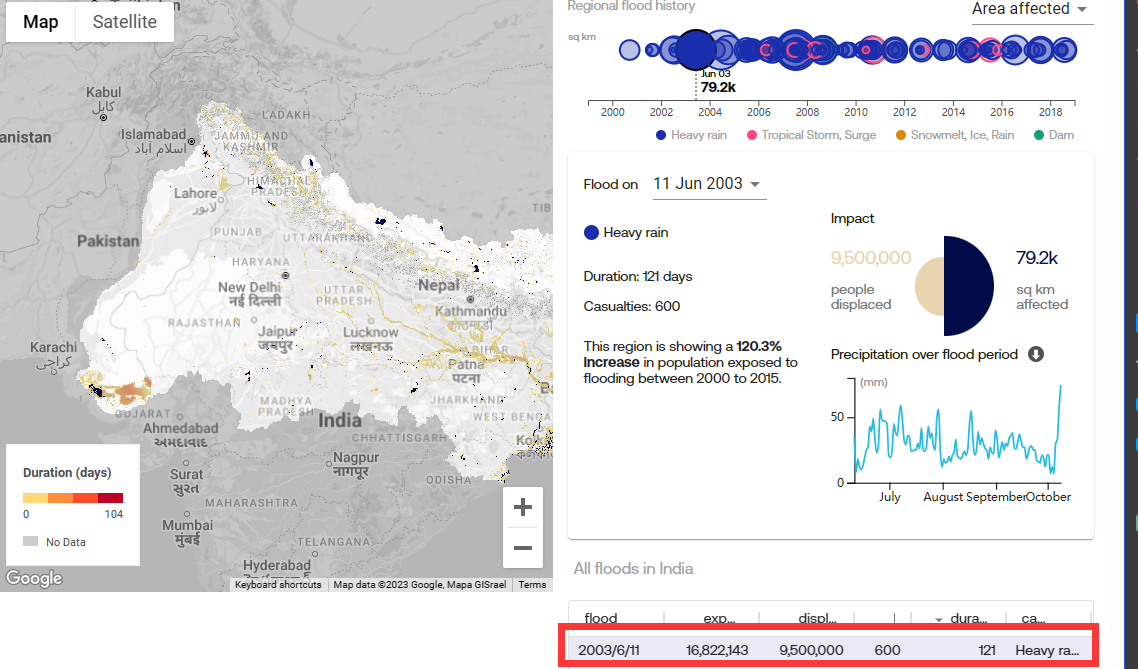

经济指标：参考[Relative Wealth Index - Humanitarian Data Exchange (humdata.org)](https://data.humdata.org/dataset/relative-wealth-index)

gdf_file = "E:\code\Py_workplace\satellite_flooding\Data\GFD\DFO_2248_From_20030611_to_20031010\DFO_2248_From_20030611_to_20031010.tif";
[gfd_A,gfd_R] = readgeoraster(gdf_file,"Bands",2);


max(max(gfd_A))

ans = single
104

min(min(gfd_A))

ans = single
0


% [pover_d_A,pover_R] = readgeoraster("E:\code\Py_workplace\satellite_flooding\Data\bgd2013incpov.tif")

within_RWI = IND_PAK_relative_wealth_index(IND_PAK_relative_wealth_index(:,1)>gfd_R.LatitudeLimits(1) & ...
                                           IND_PAK_relative_wealth_index(:,1)<gfd_R.LatitudeLimits(2) & ...
                                           IND_PAK_relative_wealth_index(:,2)>gfd_R.LongitudeLimits(1) & ...
                                           IND_PAK_relative_wealth_index(:,2)<gfd_R.LongitudeLimits(2) ...
                                            ,:);

N_RWI = length(within_RWI(:,1));



RWI_duration = zeros(N_RWI,2);  % rwi, duration
tag = 0;
% [X,Y] = geographicToDiscrete(gfd_R,lat_pi,log_pi);
for pi=1:N_RWI
    log_pi = within_RWI(pi,2);
    lat_pi = within_RWI(pi,1);
    RWI_pi = within_RWI(pi,3);
    [x,y] = geographicToDiscrete(gfd_R,lat_pi,log_pi);
    
    duration_pi = gfd_A(x,y);
    if ~isnan(duration_pi)
        if duration_pi>0
            tag = tag+1;
            RWI_duration(tag,:) = [RWI_pi, duration_pi];
            
        end
    end
end
RWI_duration = RWI_duration(1:tag,:);


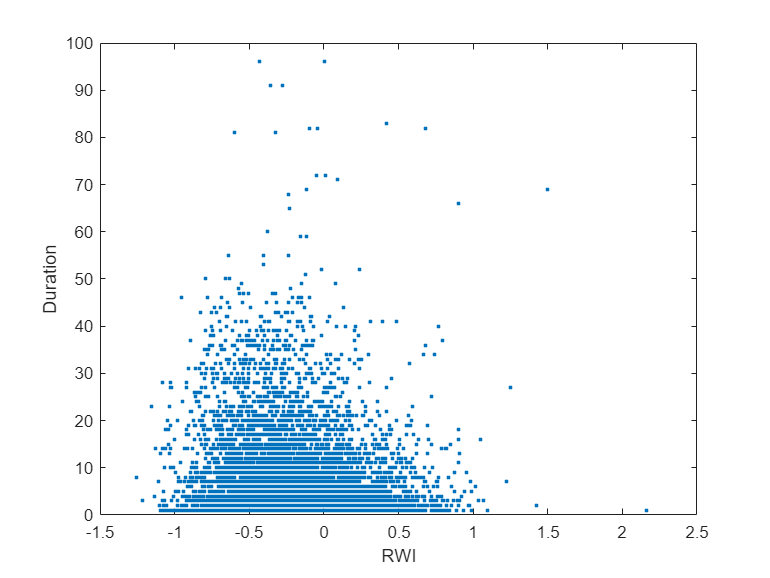

figure;
plot(RWI_duration(:,1),RWI_duration(:,2),'.');

[R3,p] = corr(RWI_duration(:,1),RWI_duration(:,2),'Type','Spearman')

R3 = -0.0905

p = 1.1059e-13

分类：按天数分为小于10天，10-20,20-30,大于30

dura_10 = RWI_duration(RWI_duration(:,2)<10,:);
dura_20 = RWI_duration(RWI_duration(:,2)<20 & ...
                       RWI_duration(:,2)>=10 ,:);
dura_30 = RWI_duration(RWI_duration(:,2)<30 & ...
                       RWI_duration(:,2)>=20 ,:);
dura_30_plus = RWI_duration(RWI_duration(:,2)>=30,:);


[mean(dura_10(:,1)), mean(dura_20(:,1)), mean(dura_30(:,1)), mean(dura_30_plus(:,1))]

ans =    -0.1913   -0.2327   -0.3205   -0.3129


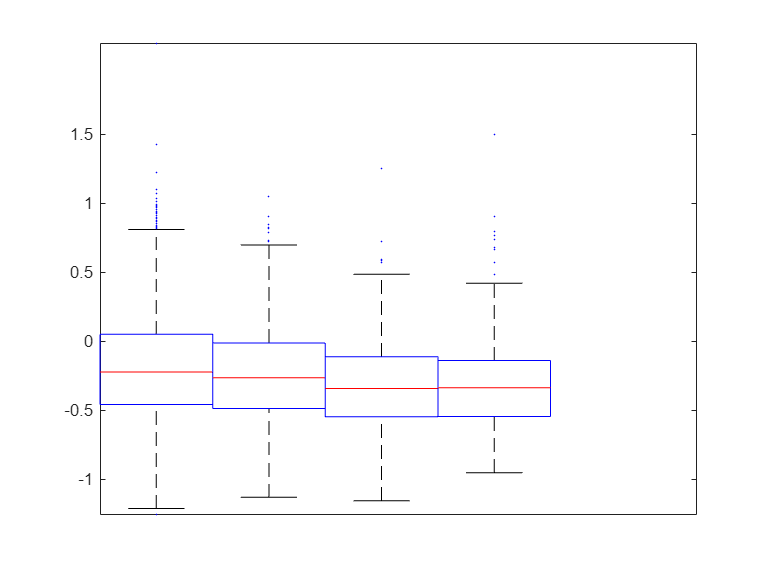

figure;
boxes_plot({{dura_10(:,1), dura_20(:,1), dura_30(:,1), dura_30_plus(:,1)}},0.1);